% === configuração ===
realSense = realsenseSubscriberSO_ARM;
j = 1;

% === coletor para zona Amarela ===
[rgbImg,depthImg] = realSense.step;
% imshow(rgbImg);
% imshow(depthImg);

% Timestamp format seguro para nomes de arquivo
t = datetime('now', 'Format', "yyyyMMdd'T'HHmmss");
ts = char(t);

% Pastas de saída
pastaRGB = "C:\Users\RoboIME\Desktop\Main Principal 1\Zona Amarela";

% Caminhos completos dos arquivos
fileRGB = fullfile(pastaRGB, "regimg" + ts + ".png");

% Salvar as imagens
imwrite(rgbImg, fileRGB);


disp("imagens salvas")

imagens salvas


j=1;
realSense = realsenseSubscriberSO_ARM;
images = {};
pClouds = {};

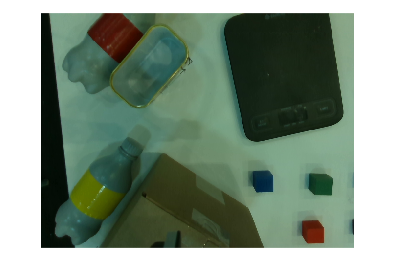

[rgbImg, depthImg] = realSense.step;
imshow(rgbImg);

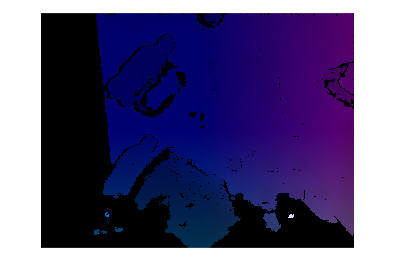

imshow(depthImg);


imwrite(rgbImg,strcat(num2str(j),'.png'),'png')
imwrite(depthImg(:,:,3),strcat(num2str(j),'_d.png'),'png')
images{j}=rgbImg;
pClouds{j}=depthImg;

j= j+1;

save('ARM_2025_Dataset1','images','pClouds')